clear

% Plant of the design
G = tf(1, [1000 50]);
G = minreal(G)

% Performance of system with no compensator
sys = feedback(G, 1)
sys_gain = dcgain(sys)
sysPerformance(sys, 0, 0, 0, 1)
title("Step response of initial system")

% P controller design
% Satisfy Ts requirement
% Recall Ts = 4/a, so a = 4/Ts = 4/5.5 = 0.8
% Find Kp to satisfy Ts.
a = 4/5.5;
Kp = 1000*a - 50
C = pid(Kp);
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, 0, 0, 10)

% Find gain to improve steady state error
syms gain
eqn = 1/(1 + gain*Kp/50) == 0.0001;
gain = double(solve(eqn, gain))

% Redesign P controller with gain
Kp = gain*Kp;
C = pid(Kp);
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, 0, 0, 1)

% Realistic setup cannot handle rise time < 0.5 seconds
% Need other controller setup

% PI controller design
% from root locus technique
Kp = 2;
Ki = 1.81;
C = pid(Kp, Ki)

C = tf([Kp Ki], [1 0])
C = minreal(C)
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, 0, 10)
% find gain to satisfy Ts
% rlocus(forwardloop) in command window

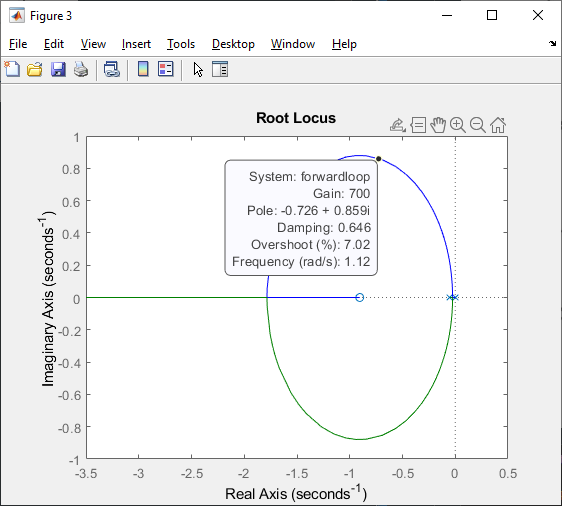

% Apply gain
gain = 700;
Kp = gain*Kp;
Ki = gain*Ki;
C = pid(Kp, Ki);
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, 0, 10)

% Increasing the gain worsens the overshoot theoretically
% Trade-off between settling time and overshoot will occur
% Try a derivative controller to control overshoot and Ts

% PD design
Kp = 1;
Ki = 0;
Kd = 1;
C = pid(Kp, Ki, Kd);
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, Kd, 10)

% Find gain to improve steady state error and Ts
% rlocus(forwardloop) in command window

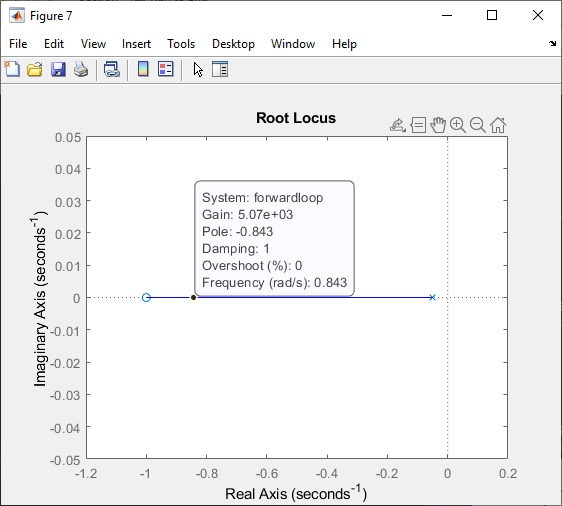

% Try gain of at least 957
% Use 5000
gain = 5000;
Kp = gain;
Ki = 0;
Kd = gain;
C = pid(Kp, Ki, Kd);
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, Kd, 10)
% Ts can be controlled and overshoot is eliminated except for error
% Possible to reduce steady state error by rise time value reaches below
% 0.5 which is unrealistic in physical setup
% Use PID controller

% Initial PID design
% Added a complex zero and pure integrator
% (Kds^2 + Kps + Ki)/s
Kp = 2;
Ki = 1.81;
Kd = 1;
C = pid(Kp, Ki, Kd)
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, Kd, 10)

% Expected the system to not satisfy requirements at this stage
% Used rlocus(forwardloop) in command window
% Designer chooses a gain of 2660 for %OS < 10.2 and Ts < 5.5.

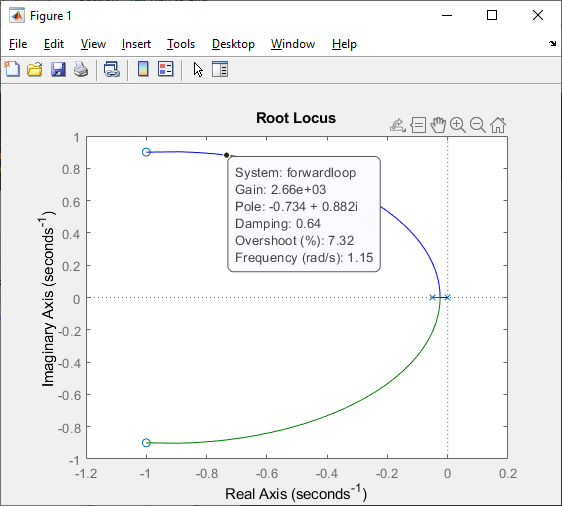

% Redesign: Apply gain 2660 to all PID coefficients
gain = 2660
Kp = gain*Kp;
Ki = gain*Ki;
Kd = gain*Kd;
C = pid(Kp, Ki, Kd)
C = tf([Kd Kp Ki], [1 0])
forwardloop = minreal(G*C)
sys = feedback(forwardloop, 1)
sysPerformance(sys, Kp, Ki, Kd, 10)

function sysPerformance(sys, Kp, Ki, Kd, input_speed)
% Step response
input_speed = 10; % input speed to the system
assess = input_speed*sys;
[y, t] = step(assess);
info = stepinfo(y, t);
clf; plot(t, input_speed*ones(size(y)), t, y, LineWidth=3)
title("Step response (Kp=" + num2str(Kp) + ", Ki=" + num2str(Ki) + ", Kd=" + num2str(Kd) + ")")
legend("Input speed", "Step response")
xlabel("Time (s)"); ylabel("Speed (m/s)")
xlim([0 max(t)])
ylim([0 1.5*input_speed])
grid on

% Steady state error
steadystateerror = (1 - dcgain(sys))*100;
Specifications = ["Overshoot (%)"; "Rise time (sec)"; "Peak time (sec)"; ...
    "Settling time (sec)"; "Steady-state error (%)"];
Obtained = [info.Overshoot; info.RiseTime; info.PeakTime; info.SettlingTime; ...
    steadystateerror];
Requirements = [10.2; 1.7 ; 3.54 ; 5.5 ; 0.01];
PerforamnceTable = table(Specifications, Obtained, Requirements)
end